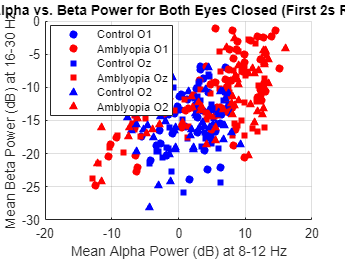

% Load participant data
load participant_data_and_severity.mat

% Define subject IDs
ID_SUBJECTS = {'A1','A3','A4','A6','A7','A8','A9','C1','C11','C12','C13','C14','C15'};

% Sampling frequency
FSAMP_HZ = 2048;

% Define filter parameters (1-100 Hz bandpass filter)
F_Nyquist_Hz = FSAMP_HZ / 2;
F_CUT1_HZ = 1;
F_CUT2_HZ = 100;
[b, a] = butter(2, [F_CUT1_HZ / F_Nyquist_Hz, F_CUT2_HZ / F_Nyquist_Hz]);

% Initialize arrays to store alpha and beta power values, labels, electrode numbers, and subject IDs for each condition
alphaValues_cond1 = []; betaValues_cond1 = []; labels_cond1 = []; electrodes_cond1 = []; subjectIDs_cond1 = [];
alphaValues_cond2 = []; betaValues_cond2 = []; labels_cond2 = []; electrodes_cond2 = []; subjectIDs_cond2 = [];
alphaValues_cond3 = []; betaValues_cond3 = []; labels_cond3 = []; electrodes_cond3 = []; subjectIDs_cond3 = [];
alphaValues_cond4 = []; betaValues_cond4 = []; labels_cond4 = []; electrodes_cond4 = []; subjectIDs_cond4 = [];

% Loop over subjects
for ii_subject = 1:length(ID_SUBJECTS)
    this_subject = ID_SUBJECTS{ii_subject};
    
    % Determine if the subject is Amblyopic (1) or Control (0)
    if startsWith(this_subject, 'A', 'IgnoreCase', true)
        subject_label = 1; % Amblyopia
    else
        subject_label = 0; % Control
    end
    
    % Extract data for this subject
    switch lower(this_subject)
        case {'a1'}
            mmsig = cat(3, A1_O1, A1_Oz, A1_O2);
        case {'a3'}
            mmsig = cat(3, A3_O1, A3_Oz, A3_O2);
        case {'a4'}
            mmsig = cat(3, A4_O1, A4_Oz, A4_O2);
        case {'a6'}
            mmsig = cat(3, A6_O1, A6_Oz, A6_O2);
        case {'a7'}
            mmsig = cat(3, A7_O1, A7_Oz, A7_O2);
        case {'a8'}
            mmsig = cat(3, A8_O1, A8_Oz, A8_O2);
        case {'a9'}
            mmsig = cat(3, A9_O1, A9_Oz, A9_O2);
        case {'c1'}
            mmsig = cat(3, C1_O1, C1_Oz, C1_O2);
        case {'c11'}
            mmsig = cat(3, C11_O1, C11_Oz, C11_O2);
        case {'c12'}
            mmsig = cat(3, C12_O1, C12_Oz, C12_O2);
        case {'c13'}
            mmsig = cat(3, C13_O1, C13_Oz, C13_O2);
        case {'c14'}
            mmsig = cat(3, C14_O1, C14_Oz, C14_O2);
        case {'c15'}
            mmsig = cat(3, C15_O1, C15_Oz, C15_O2);
        otherwise
            error("Unknown subject ID.");
    end
    
    % Now, for each electrode
    for ii_elec = 1:3
        msig = mmsig(:, :, ii_elec); % msig is (samples x conditions)
        
        % Process conditions:
        % ix_sig = 1: Both Eyes Closed
        % ix_sig = 2: Both Eyes Open
        % ix_sig = 3: Dominant Eye Closed
        % ix_sig = 4: Non-Dominant Eye Closed
        for ix_sig = 1:4
            sig = msig(:, ix_sig);
            % Filter the signal
            sig = filter(b, a, sig);
            
            % Remove the first 2 seconds of data
            samples_to_skip = FSAMP_HZ * 2; % Number of samples in 2 seconds
            sig = sig(samples_to_skip + 1:end);
            
            % Segment the signal into 1-second segments
            n_samples = length(sig);
            segment_length = FSAMP_HZ * 1; % 1-second segments
            n_segments = floor(n_samples / segment_length); % Number of full segments
            
            % Loop over each 1-second segment
            for ix_seg = 1:n_segments
                % Extract the segment
                start_idx = (ix_seg - 1) * segment_length + 1;
                end_idx = ix_seg * segment_length;
                segment = sig(start_idx:end_idx);
                
                % Compute alpha and beta power
                [alphaPower, betaPower] = computePower(segment, FSAMP_HZ);
                
                % Append values to arrays based on condition
                if ix_sig == 1 % Both Eyes Closed
                    alphaValues_cond1 = [alphaValues_cond1; alphaPower];
                    betaValues_cond1 = [betaValues_cond1; betaPower];
                    labels_cond1 = [labels_cond1; subject_label];
                    electrodes_cond1 = [electrodes_cond1; ii_elec];
                    subjectIDs_cond1 = [subjectIDs_cond1; ii_subject]; % Add subject index
                elseif ix_sig == 2 % Both Eyes Open
                    alphaValues_cond2 = [alphaValues_cond2; alphaPower];
                    betaValues_cond2 = [betaValues_cond2; betaPower];
                    labels_cond2 = [labels_cond2; subject_label];
                    electrodes_cond2 = [electrodes_cond2; ii_elec];
                    subjectIDs_cond2 = [subjectIDs_cond2; ii_subject]; % Add subject index
                elseif ix_sig == 3 % Dominant Eye Closed
                    alphaValues_cond3 = [alphaValues_cond3; alphaPower];
                    betaValues_cond3 = [betaValues_cond3; betaPower];
                    labels_cond3 = [labels_cond3; subject_label];
                    electrodes_cond3 = [electrodes_cond3; ii_elec];
                    subjectIDs_cond3 = [subjectIDs_cond3; ii_subject]; % Add subject index
                elseif ix_sig == 4 % Non-Dominant Eye Closed
                    alphaValues_cond4 = [alphaValues_cond4; alphaPower];
                    betaValues_cond4 = [betaValues_cond4; betaPower];
                    labels_cond4 = [labels_cond4; subject_label];
                    electrodes_cond4 = [electrodes_cond4; ii_elec];
                    subjectIDs_cond4 = [subjectIDs_cond4; ii_subject]; % Add subject index
                
                end
            end
        end
    end
end

% Define markers for electrodes
electrode_markers = {'o', 's', '^'}; % O1: circle, Oz: square, O2: triangle

% Plotting for Both Eyes Closed Condition
figure;
hold on;
for electrode = 1:3
    % Get indices for this electrode
    idx_electrode = (electrodes_cond1 == electrode);
    % Plot Control subjects
    idx_control = idx_electrode & (labels_cond1 == 0);
    scatter(alphaValues_cond1(idx_control), betaValues_cond1(idx_control), 'b', electrode_markers{electrode}, 'filled');
    % Plot Amblyopia patients
    idx_amblyopia = idx_electrode & (labels_cond1 == 1);
    scatter(alphaValues_cond1(idx_amblyopia), betaValues_cond1(idx_amblyopia), 'r', electrode_markers{electrode}, 'filled');
end
legend({'Control O1', 'Amblyopia O1', 'Control Oz', 'Amblyopia Oz', 'Control O2', 'Amblyopia O2'}, 'Location', 'best');
xlabel('Mean Alpha Power (dB) at 8-12 Hz');
ylabel('Mean Beta Power (dB) at 16-30 Hz');
title('Mean Alpha vs. Beta Power for Both Eyes Closed (First 2s Removed)');
grid on;
hold off;

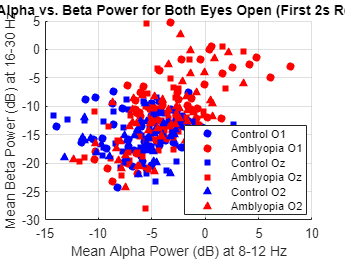


% Plotting for Both Eyes Open Condition
figure;
hold on;
for electrode = 1:3
    idx_electrode = (electrodes_cond2 == electrode);
    idx_control = idx_electrode & (labels_cond2 == 0);
    scatter(alphaValues_cond2(idx_control), betaValues_cond2(idx_control), 'b', electrode_markers{electrode}, 'filled');
    idx_amblyopia = idx_electrode & (labels_cond2 == 1);
    scatter(alphaValues_cond2(idx_amblyopia), betaValues_cond2(idx_amblyopia), 'r', electrode_markers{electrode}, 'filled');
end
legend({'Control O1', 'Amblyopia O1', 'Control Oz', 'Amblyopia Oz', 'Control O2', 'Amblyopia O2'}, 'Location', 'best');
xlabel('Mean Alpha Power (dB) at 8-12 Hz');
ylabel('Mean Beta Power (dB) at 16-30 Hz');
title('Mean Alpha vs. Beta Power for Both Eyes Open (First 2s Removed)');
grid on;
hold off;

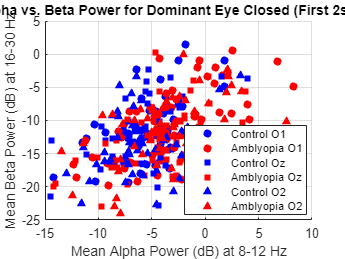


% Plotting for Dominant Eye Closed Condition
figure;
hold on;
for electrode = 1:3
    idx_electrode = (electrodes_cond3 == electrode);
    idx_control = idx_electrode & (labels_cond3 == 0);
    scatter(alphaValues_cond3(idx_control), betaValues_cond3(idx_control), 'b', electrode_markers{electrode}, 'filled');
    idx_amblyopia = idx_electrode & (labels_cond3 == 1);
    scatter(alphaValues_cond3(idx_amblyopia), betaValues_cond3(idx_amblyopia), 'r', electrode_markers{electrode}, 'filled');
end
legend({'Control O1', 'Amblyopia O1', 'Control Oz', 'Amblyopia Oz', 'Control O2', 'Amblyopia O2'}, 'Location', 'best');
xlabel('Mean Alpha Power (dB) at 8-12 Hz');
ylabel('Mean Beta Power (dB) at 16-30 Hz');
title('Mean Alpha vs. Beta Power for Dominant Eye Closed (First 2s Removed)');
grid on;
hold off;

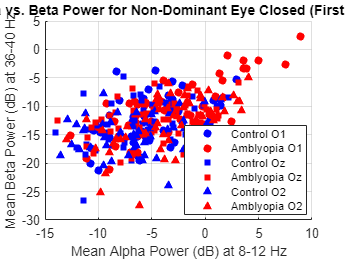


% Plotting for Non-Dominant Eye Closed Condition
figure;
hold on;
for electrode = 1:3
    idx_electrode = (electrodes_cond4 == electrode);
    idx_control = idx_electrode & (labels_cond4 == 0);
    scatter(alphaValues_cond4(idx_control), betaValues_cond4(idx_control), 'b', electrode_markers{electrode}, 'filled');
    idx_amblyopia = idx_electrode & (labels_cond4 == 1);
    scatter(alphaValues_cond4(idx_amblyopia), betaValues_cond4(idx_amblyopia), 'r', electrode_markers{electrode}, 'filled');
end
legend({'Control O1', 'Amblyopia O1', 'Control Oz', 'Amblyopia Oz', 'Control O2', 'Amblyopia O2'}, 'Location', 'best');
xlabel('Mean Alpha Power (dB) at 8-12 Hz');
ylabel('Mean Beta Power (dB) at 36-40 Hz');
title('Mean Alpha vs. Beta Power for Non-Dominant Eye Closed (First 2s Removed)');
grid on;
hold off;


% Optionally, save the data
combinedData_cond1 = [alphaValues_cond1, betaValues_cond1, labels_cond1, electrodes_cond1, subjectIDs_cond1];
combinedData_cond2 = [alphaValues_cond2, betaValues_cond2, labels_cond2, electrodes_cond2, subjectIDs_cond2];
combinedData_cond3 = [alphaValues_cond3, betaValues_cond3, labels_cond3, electrodes_cond3, subjectIDs_cond3];
combinedData_cond4 = [alphaValues_cond4, betaValues_cond4, labels_cond4, electrodes_cond4, subjectIDs_cond4];
save('combinedEEGData_cond1.mat', 'combinedData_cond1');
save('combinedEEGData_cond2.mat', 'combinedData_cond2');
save('combinedEEGData_cond3.mat', 'combinedData_cond3');
save('combinedEEGData_cond4.mat', 'combinedData_cond4');



Leave-One-Subject-Out Cross-Validation Results:


Subject 1 Accuracy: 100.00%
Subject 2 Accuracy: 16.67%
Subject 3 Accuracy: 100.00%
Subject 4 Accuracy: 54.17%
Subject 5 Accuracy: 4.17%
Subject 6 Accuracy: 20.83%
Subject 7 Accuracy: 95.83%
Subject 8 Accuracy: 54.17%
Subject 9 Accuracy: 50.00%
Subject 10 Accuracy: 83.33%
Subject 11 Accuracy: 45.83%
Subject 12 Accuracy: 50.00%
Subject 13 Accuracy: 66.67%


Overall Random Forest Accuracy: 57.05%


% Function to compute alpha and beta power

function [alphaPower, betaPower] = computePower(sig, FSAMP_HZ)
    % sig: the EEG segment
    % FSAMP_HZ: sampling frequency
    
    % Length of the signal
    L = length(sig);
    
    % Fourier Transform
    Fsig = fft(sig) / L;
    % Take only positive frequencies
    Fsig = Fsig(1:floor(L/2)+1);
    aFsig = abs(Fsig);
    f_axis_Hz = FSAMP_HZ * (0:(L/2)) / L;
    
    % Power Spectrum
    p_spectrum = (aFsig).^2;
    % Convert to dB
    p_spectrum_dB = 10*log10(p_spectrum);
    
    % Extracting Alpha and Beta Power
    mask_alpha = (f_axis_Hz >= 8 & f_axis_Hz <= 12);
    alphaPower = mean(p_spectrum_dB(mask_alpha));
    mask_beta = (f_axis_Hz > 36 & f_axis_Hz <= 40);
    betaPower = mean(p_spectrum_dB(mask_beta));
end
